clc
clear
close all

## **Modelo**

%   dv/dt = -a/m * v + b/m * u - d
%   d = g * sin(α)

% Parámetros
m = 1000;
a = 200;
b = 10000;
g = 9.82;
dt = 0.001;
t = 0:dt:30;
%alpha = 0; % sin perturbación por ahora
alpha = zeros(size(t));
d = g * sin(alpha);

## Consigna

r = 25*ones(size(t));
r(t > 10) = 30; % Escalón en t = 10 s

## Ley de control

Kp = 1;
Ki = 0.1;
u = zeros(size(t));

## Modelo dinámico

v = zeros(size(t));
I = 0;
%dt = 0.1;
for i = 2:length(t)
    e = r(i-1) - v(i-1);
    I = I+ e*dt;
    u(i-1) = Kp * e + Ki * I;
    dv = (-a/m)*v(i-1) + (b/m)*u(i-1) - d(i-1);
    v(i) = v(i-1) + dv*dt;
end

## Plot

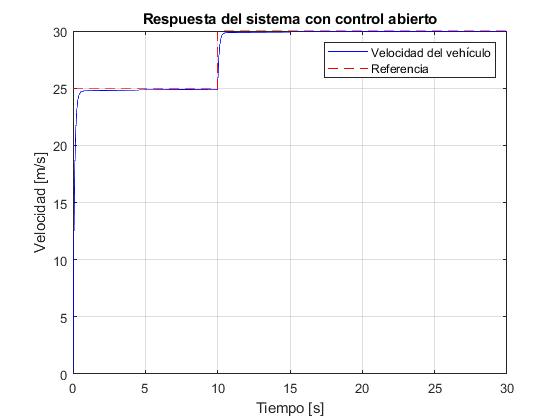

plot(t, v, 'b', t, r, 'r--');
hold on
grid on
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');
legend('Velocidad del vehículo', 'Referencia');
title('Respuesta del sistema con control abierto');
hold off

## Agregado de perturbacion alfa = 2°

alpha(t>=20) = deg2rad(2);
d = g * sin(alpha);

I = 0;
v = zeros(size(t));
dv = zeros(size(t));
%dt = 0.1;
for i = 2:length(t)
    e = r(i-1) - v(i-1);
    I = I+ e*dt;
    u(i-1) = Kp * e + Ki*I;
    dv = (-a/m)*v(i-1) + (b/m)*u(i-1) - d(i-1);
    v(i) = v(i-1) + dv*dt;
end

## Plot con perturbación

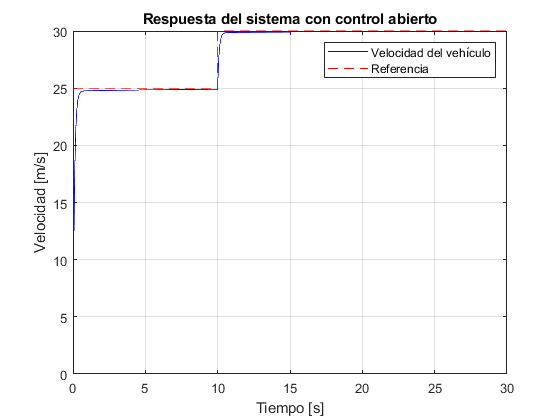

plot(t, v, 'b', t, r, 'r--');
hold on
grid on
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');
legend('Velocidad del vehículo', 'Referencia');
title('Respuesta del sistema con control abierto');
hold off

## Cambio de m = 1500 kg

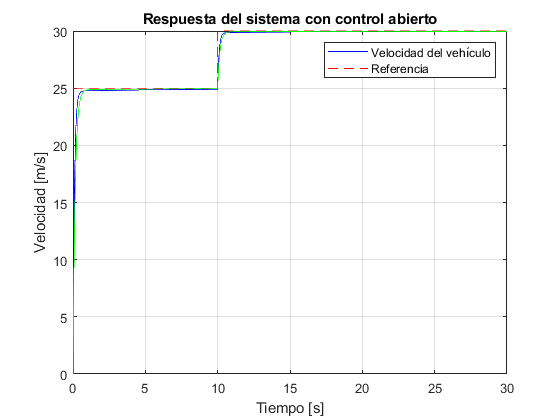

m = 1500;
v2 = zeros(size(t));
%dt = 0.1;
I = 0;
for i = 2:length(t)
    e = r(i-1) - v2(i-1);
    I = I + e*dt;
    u(i-1) = Kp * e + Ki * I;
    dv2 = (-a/m)*v2(i-1) + (b/m)*u(i-1) - d(i-1);
    v2(i) = v2(i-1) + dv2*dt;
end

plot(t, v, 'b', t, r, 'r--', t,v2, 'green');
hold on
grid on
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');
legend('Velocidad del vehículo', 'Referencia');
title('Respuesta del sistema con control abierto');
hold off